clear; close all;

## Lab 6

### Confidence Interval

Throughout everything physics, infact throughout science, we see different confidence intervals. The confidence interval is the range of values where we are confident that we have a signal. You see them everywhere they appear something like this; the intensity of the star is $9\ldotp 2\pm 0\ldotp 8$. The $\pm$ values come from one standard deviation out from the measured value. This gives us an interval where we are 68% confindent that the signal lays within those bounds. If there is a symetric background distribution then the range is even on both sides, however if the distribution is from an asymetric distribution then the $\pm$ will also be asymetric and the + can be a different value as the - (based on the standard deviations). 

We are wanting to study the LHC data for the remainder of the labs so how does this relate to our data. In particle physics it is very difficult to find exactly where different properties are. This means that confidence intervals are very important to properly report findings. Along side confidence intervals finding upper/lower limits is hugely important to limit the search range for different particles which reduces search times and ultimatly saves money. To demonstrate the confidence interval in our data we will simulate a background from a poisson distribution with a high mean of 100.

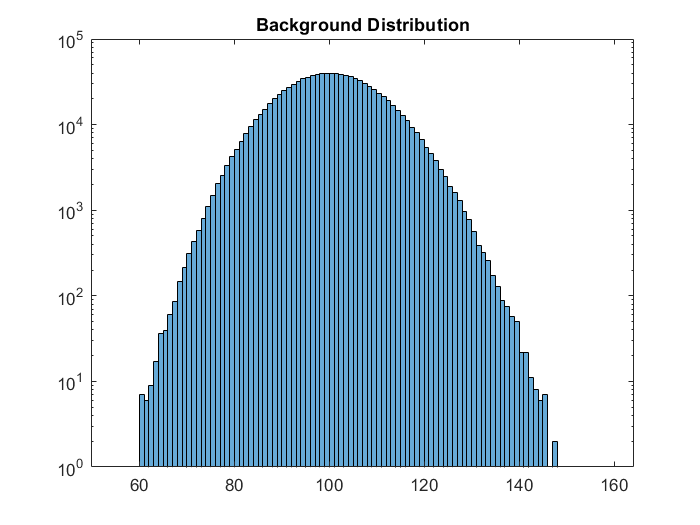

fakedata = poissrnd(100,1,1000000);
histogram(fakedata,'BinWidth',1)
set(gca,'YScale','log')
title('Background Distribution')

### Problem 1: Five Sigma Range

We want to demostrat the confidence interval but we still want to find a statistcally significant value, to do this we will find the five sigma range just like we have in many other labs before. 

prob_5_U = normcdf(5,"upper");
prob_5_L = normcdf(5);
fakeinv = poissinv(prob_5_U,100);
fakeinv2 = poissinv(prob_5_L,100);
fakeinv;
fakeinv2;

After calculating the five sigma we would need to see a signal below 54 and above 154 in order to find a five sigma detection from our background.

### Problem 2: Single Injected Signal

The way that we find our confidence interval is we want to inject fake data into our background. When we inject the fake data into the background the signal that we see is also affected by the background. We want to demostrate this with a large signal of eight sigma.

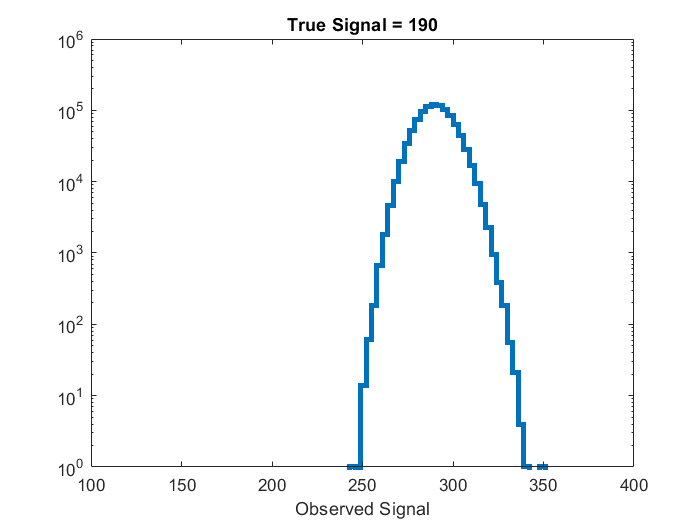

prob8 = normcdf(8);
fake_signal = poissinv(prob8,100);
fake_signal;

newdata = fakedata + fake_signal;
histogram(newdata,'BinWidth',3,'DisplayStyle','stairs','LineWidth',3)
title('True Signal = 190')
xlabel('Observed Signal')
xlim([100 400])
set(gca,'YScale','log')

After injecting the signal to the background and plotting the data you can see that it takes the same form as the background distribution bu shifted up by the value of the fake signal of 190. The observed signal is slighty biased because it is a Poisson distribution, however because we have a large mean the Poisson distribution becomes more and more like a normal distribution so there is a slight skewing to the left and therefore more likely to be less than the observed signal. This means that if we were to make a confidence interval from this data we would have an asymetric +/- spread, however because the Poisson distribution is very close to a guassian it wouldn't be too inaccurate to consider this a symetric distribution.

### Problem 3: Many Injected Signals

We want to create an array of many different injected signals to test and see what we would observe given many possible signals. To do this we create a distribution of fake signals from a uniform distribution. (It is extremely important to use a uniform distribution otherwise we create an implicit prior and make a large statisical error.) This distribution ranges from 0 - 400 to give us a large range of sigmas that may happen.

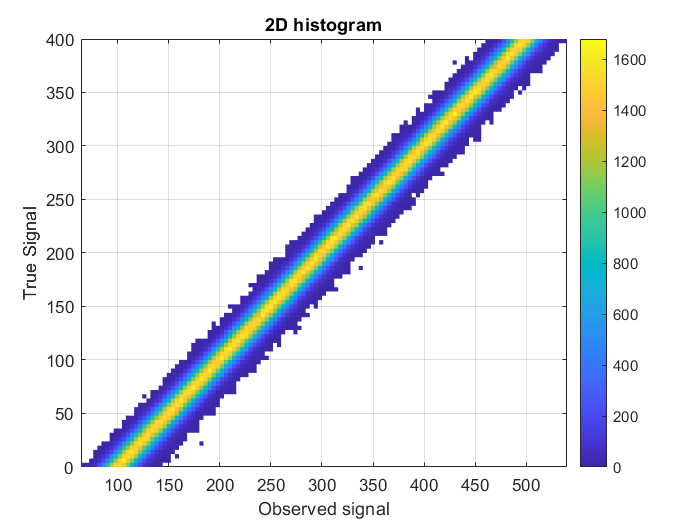

injsignal = unifrnd(0,400,1,1000000);
data = fakedata + injsignal;

H = histogram2(data,injsignal,'BinWidth',4,'DisplayStyle','tile');
colorbar
title('2D histogram')
xlabel('Observed signal')
ylabel('True Signal')

After generating the data and doing the same thing as in the above problem where we add the injected data into the background data we create many distributions such as the one in problem 2. If we plot this on a two-dimensional histogram we can see what this looks like. 

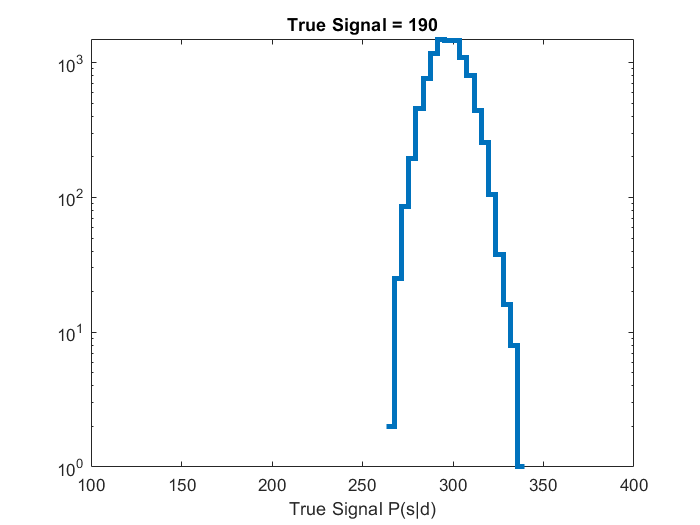

[T,A,B] = histcounts2(data,injsignal,[119 100]);
hor = T(:,50);

stairs(A(1:end-1),hor,'LineWidth',3)
title('True Signal = 190')
xlabel('True Signal P(s|d)')
xlim([100 400])
set(gca,'Yscale','log')

If we take a verticle "slice" across the 2D histogram we can extract the same graph that we had in the problem above. 

We can also take a horizontal "slice" across the graph if we want to see the range of true signals that could of have given us a given observed signal.

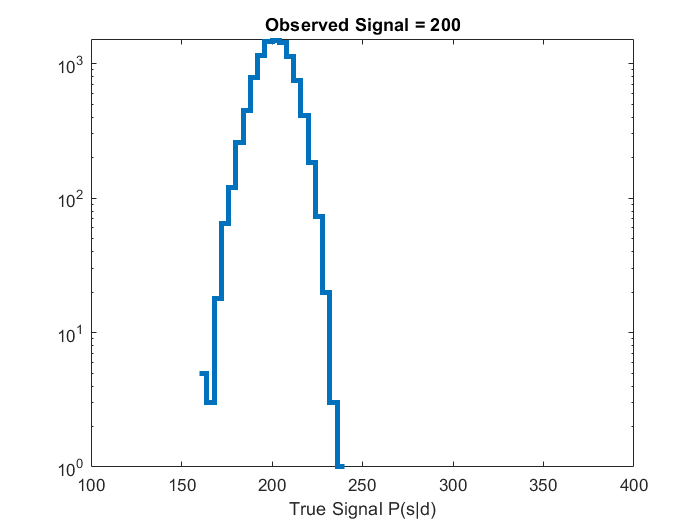

vert = T(60,:);
stairs(B(1:end-1),vert,'LineWidth',3)
title('Observed Signal = 200')
xlabel('True Signal P(s|d)')
xlim([100 400])
set(gca,'Yscale','log')


range = std(data(500000:700000))/2;

From this data we can extrapolate the standard deviation and then compute our confidence interval. From the data we can see that one standard deviation in each direction is about 58. Therefore the confidence interval is $200\pm 58$ on the signal that we selected. The interval can be treated as symetric because a Poisson distribution becomes a normal distribution for high mean values. This process gives us the range that an observed signal could come from different true signals. 

All the above is the process for using Bayes' Theorem. Bayes' Theorem is: $P\left(\mathrm{signal}|\mathrm{data}\right)=\frac{P\left(\mathrm{data}|\mathrm{signal}\right)P\left(\mathrm{signal}\right)}{P\left(\mathrm{data}\right)}$ this reads as "given a data reading, the probability it was produced by a given true signal $\left(P\left(\mathrm{signal}|\mathrm{data}\right)\right)$, is equal to the probability of getting a particular data reading given a certain true signal $\left(P\left(\mathrm{data}|\mathrm{signal}\right)\right)$ times the probability of the signal having a particular strength $\left(P\left(\mathrm{signal}\right)\right)$, divided by the probability of each data reading $\left(P\left(\mathrm{data}\right)\right)$." (from HW5). 

The $P\left(\mathrm{signal}\right)$is called the prior. The prior that we used above was the injected signal, in this case a flat prior was used because we used a uniform distribution, a flat prior needs to be used otherwise this process is invald. 